# Complex-symbol-to-bits Demapping for IQ Modulations

This functions demaps a complex symbol stream into a bit stream with respect to some QAM constellations using gray coding.

**Inputs:**

- *symb_RX_estimated*: estimated symbol stream vector of size *nb_symb x 1*

- *nb_bit_per_symb*: number of bits per symbol

- *nb_symb*: number of symbols in the  symbol stream (= length of *symb_RX*)

**Ouputs:**

- *bit_RX*: estimated bit stream vector of size *nb_bit x 1* where *nb_bit = nb_bit_per_symb x nb_symb*

function bit_RX = demapping_QAM( symb_RX_estimated , nb_bit_per_symb , nb_symb )

nb_bit = nb_symb * nb_bit_per_symb ;                  % Number of bits of the bit stream
bit_RX = zeros( nb_bit , 1 ) ;                        % Bit stream vector initialization

## 4QAM constellation (<=> QPSK)

The de-mapping for the QPSK constellation should be done as shown below:

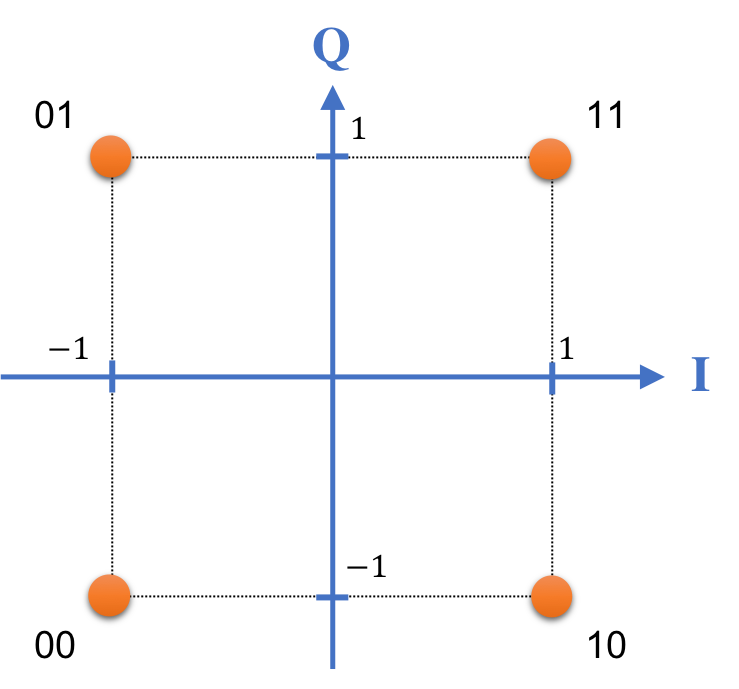

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 2

    % QPSK demapping with Gray coding (minimum-distance detector)
    constellation = [ -1-1j, -1+1j, +1-1j, +1+1j ] ;
    bit_table     = [ 0 0 ;  0 1 ;  1 0 ;  1 1 ] ;

    % Find closest constellation point for each estimated symbol
    dist = abs( symb_RX_estimated - constellation ) ;       % nb_symb x 4
    [ ~ , idx ] = min( dist , [] , 2 ) ;

    % Map indices to bit patterns
    bit_matrix = bit_table( idx , : ) ;                     % nb_symb x 2
    bit_RX = reshape( bit_matrix.' , nb_bit , 1 ) ;

end


## 16QAM constellation

The de-mapping for the 16QAM constellation should be done as shown below:

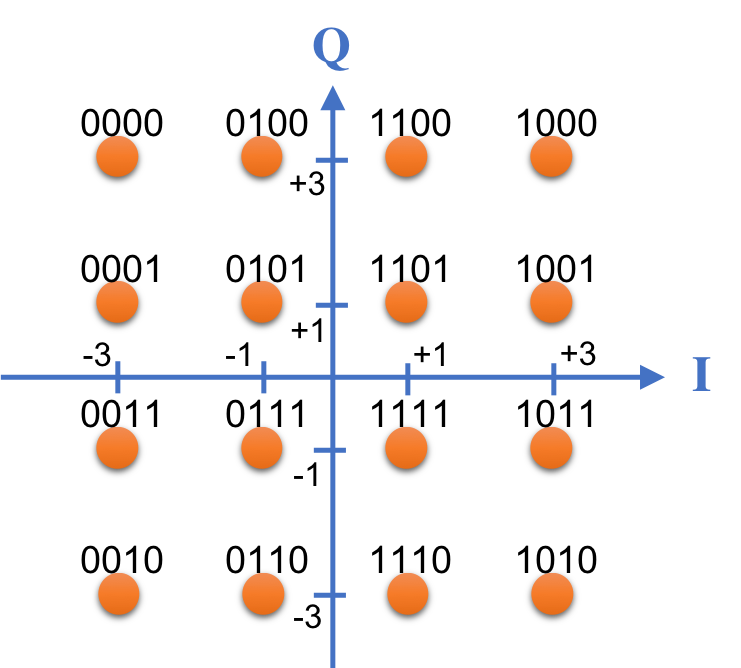

This mapping follows a gray coding: each symbol differs from its neighbors by one bit only. This reduces bit errors as a received symbol distorted by some noise is more likely to fall close to an adjacent symbol  than close to a faraway symbol. 

if nb_bit_per_symb == 4

    % 16QAM demapping with Gray coding (vectorized, minimum-distance detector)
    constellation = [ -3+3j, -3+1j, -3-3j, -3-1j, ...
                      -1+3j, -1+1j, -1-3j, -1-1j, ...
                      +3+3j, +3+1j, +3-3j, +3-1j, ...
                      +1+3j, +1+1j, +1-3j, +1-1j ] ;

    bit_table = [ 0 0 0 0 ; 0 0 0 1 ; 0 0 1 0 ; 0 0 1 1 ; ...
                  0 1 0 0 ; 0 1 0 1 ; 0 1 1 0 ; 0 1 1 1 ; ...
                  1 0 0 0 ; 1 0 0 1 ; 1 0 1 0 ; 1 0 1 1 ; ...
                  1 1 0 0 ; 1 1 0 1 ; 1 1 1 0 ; 1 1 1 1 ] ;

    dist = abs( symb_RX_estimated - constellation ) ;       % nb_symb x 16
    [ ~ , idx ] = min( dist , [] , 2 ) ;

    bit_matrix = bit_table( idx , : ) ;                     % nb_symb x 4
    bit_RX = reshape( bit_matrix.' , nb_bit , 1 ) ;

end

end